# PRMIA Risk Management Challenge --------- MATLAB Challenge Livescript

## Krushna Mehta      Qiwen Wang      Yuanhao Feng      Jiewei Wu

### Positions

First, the market data obtained from exchange market API should be updated tickly for traders to monitor. Here we just read the relevant data from csv files for outlook.

data = readtable('position.csv','PreserveVariableNames',true);
fig = uifigure('Position',[500 500 750 350]);
uit = uitable(fig);
uit.Position = [20 20 710 310];
uit.Data = data;
data = table2array(data(:,2:9));
uit.RowName = 'numbered';
[row, col] = find(data(:,8) > 0);
col = col + 8;
s = uistyle('BackgroundColor','green');
addStyle(uit,s,'cell',[row,col]);
[row, col] = find(data(:,8) < 0);
col = col + 8;
s = uistyle('BackgroundColor','red');
addStyle(uit,s,'cell',[row,col]); 

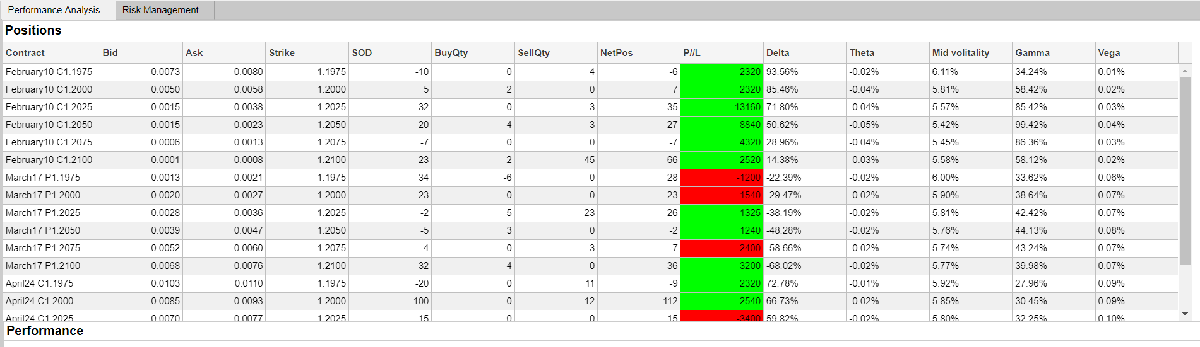

Once run the above code, A winow of uitable of this will be poped up. The P&L column is colored for visibility.

By clicking the Load botton,the code will ask you to select your portfolio file. Once you select the file(which is a csv or excel file), the code will read the position and the currency price and volatility data.

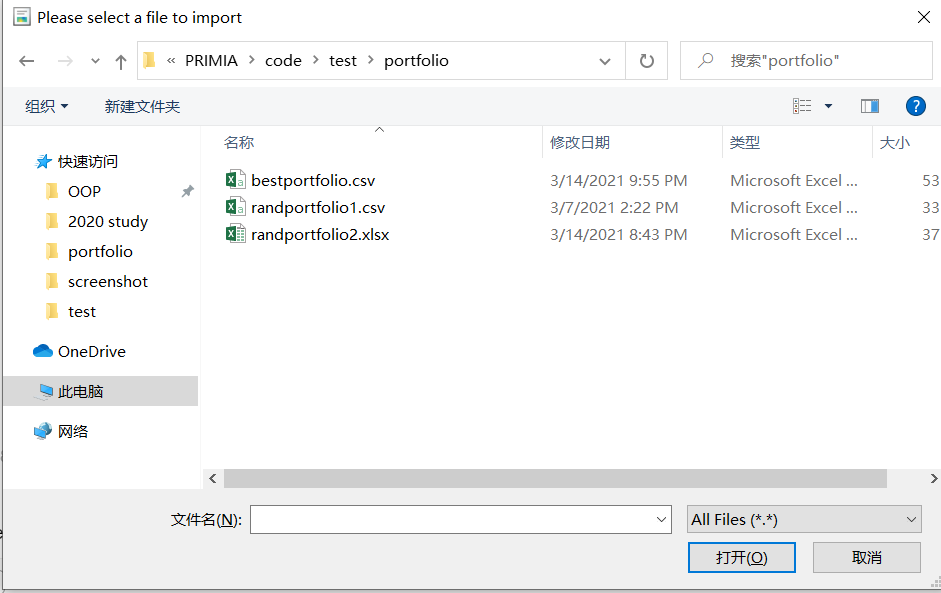

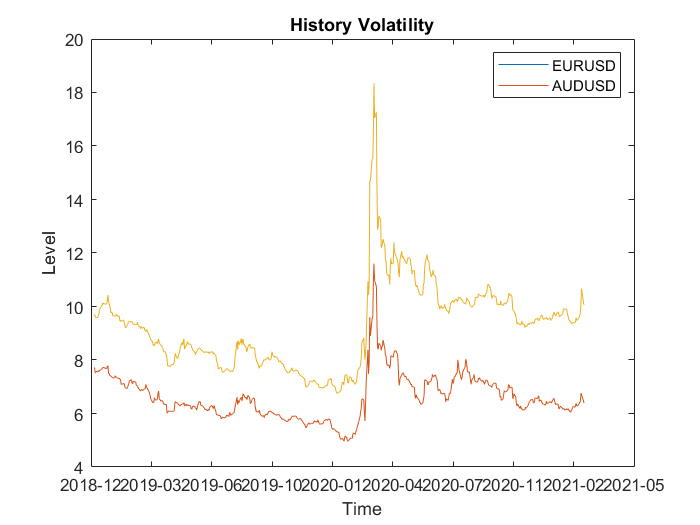

[file_name, file_path] = uigetfile('*.*', 'Please select a file to import');
positionS = readtable(convertCharsToStrings(file_path) + "\" +...
convertCharsToStrings(file_name),'PreserveVariableNames',true);

position = positionS;
file_name = split(convertCharsToStrings(file_name),'.');
portfolio_name = file_name(1);

vol_data = readtable('currency_impliedvol.csv','PreserveVariableNames',true);
vol_table = vol_data;
date = datenum(vol_data.Date);
figure(1);
plot(date, vol_data.EURUSD);
hold on;
plot(date, vol_data.AUDUSD);
datetick('x', 'yyyy-mm', 'keepticks');
legend('EURUSD','AUDUSD');
title('History Volatility');
xlabel('Time')
ylabel('Level');  

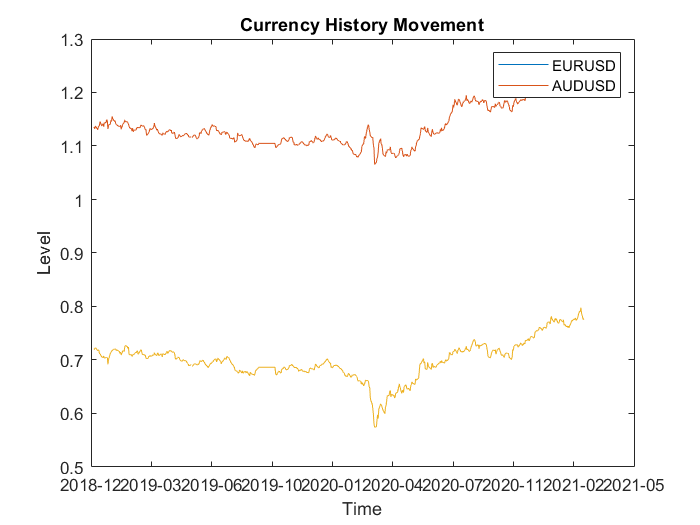


currency_data = readtable('Currency.csv','PreserveVariableNames',true);
currency_table = currency_data;
date = datenum(currency_data.Date);
figure(2)
plot(date, currency_data.EURUSD);
hold on;
plot(date, currency_data.AUDUSD);
datetick('x', 'yyyy-mm', 'keepticks')
legend('EURUSD','AUDUSD');
title('Currency History Movement');
xlabel('Time')
ylabel('Level'); 

### Performance

Reinvest

Reinvest = true;

Transaction Cost

TransactionCost = false;

Apply Botton

 ;

By choosing reinvest and transaction cost or not, by clicking the apply botton, we are able to simulate our previous uploaded portfolio.

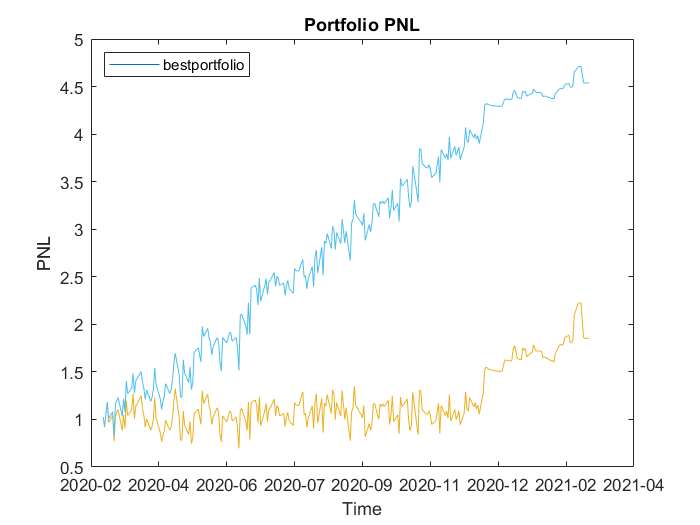

price = readtable('OptionPrice.csv','PreserveVariableNames',true);
difference = diff(price{:,2:end});
price{:,2:end}(ismissing(price{:,2:end})) = 0;
daily_capital = sum(price{:,2:end} .* position{:,2:end},2);
price{1:end-1,2:end} = difference;
price{:,2:end}(ismissing(price{:,2:end})) = 0;
price{end,2:end} = 0;
pnl = price{:,2:end} .* position{:,2:end};
if TransactionCost == 1
    app.portfolio_name = app.portfolio_name + "Cost";
    pnl(1:end-1,:) = pnl(1:end-1,:) - ...
        0.02*abs(diff(app.position{:,2:end}).*price{1:end-1,2:end});
end
daily_pnl = sum(pnl,2);
daily_return = daily_pnl./daily_capital; 
acc_pnl = 1 + cumsum(daily_return);
date = datenum(price.Date);


figure(3)
plot(date, acc_pnl);
hold('on');
datetick('x', 'yyyy-mm', 'keepticks');
legend(sprintf("%s", portfolio_name),'Location','northwest');
title('Portfolio PNL');
xlabel('Time');
ylabel('PNL');  
hold('on');

In the dashboard, we also realized start and end date selection, multiple portoflio draw in one plot, and multi-labels interface. Numerically, we also calculated final capital for initialized capital and performance statistics which are necessary to analyze a portfolio, which looks like follows. I emphasize these points in the video demo.

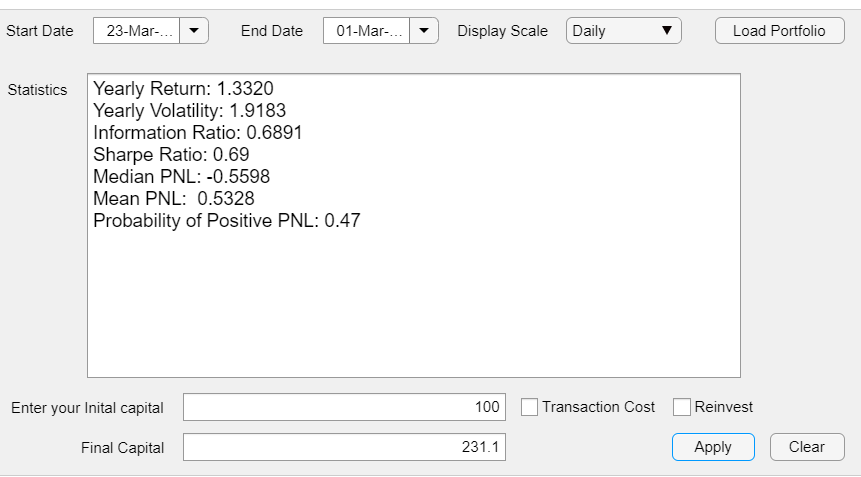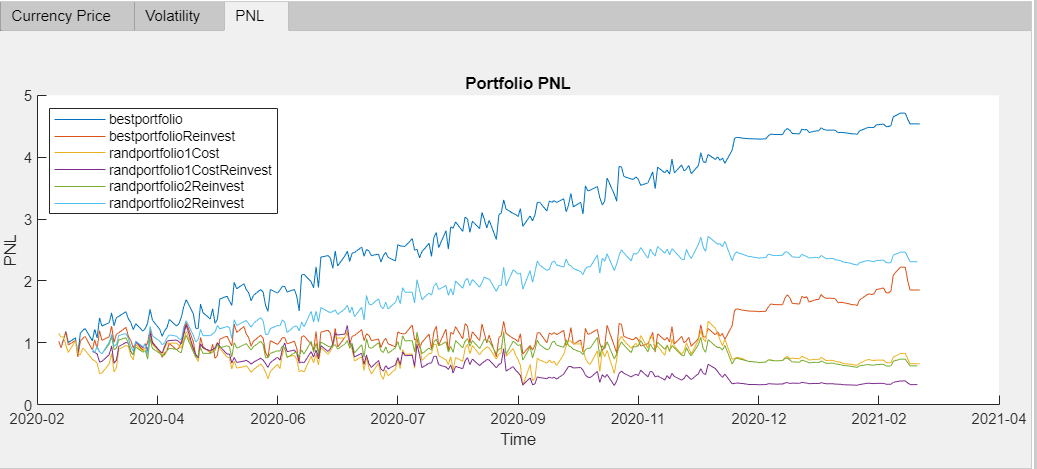

### VaR and ES Backtesting

With the daily P&L obtained from the previous section, we can do VaR and ES backtesting. 

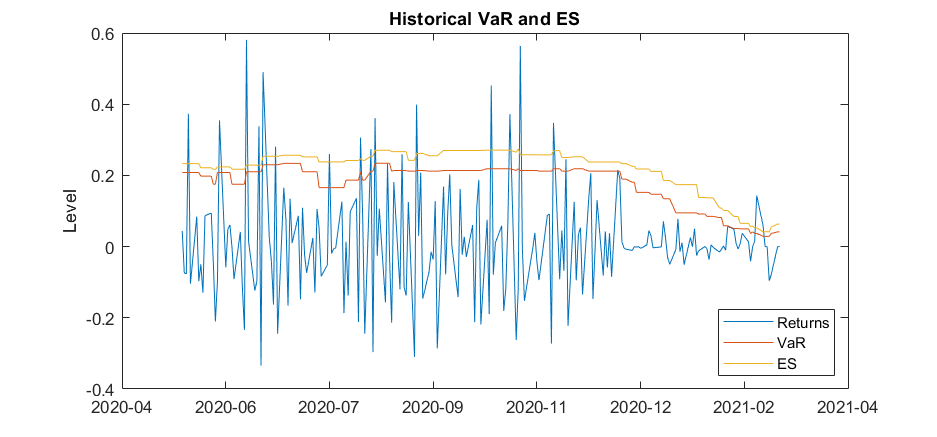

VaRLevel = 0.9;
VaRLevel = 0.9;
 ;
Returns = daily_return;
DateReturns = price.Date;
TestWindowStart = 1;
TestWindowEnd = length(DateReturns);

EstimationWindowSize = 50;
TestWindow = TestWindowStart+EstimationWindowSize:TestWindowEnd;


DatesTest = DateReturns(TestWindow);
ReturnsTest = Returns(TestWindow);


VaR_Hist = zeros(length(TestWindow) ,1);
ES_Hist = zeros(length(TestWindow),1);

for t = TestWindow
   
   i = t - TestWindowStart + 1;
   EstimationWindow = t-EstimationWindowSize:t-1;
   
   [VaR_Hist(i - EstimationWindowSize),ES_Hist(i - EstimationWindowSize)]...
       = hHistoricalVaRES(Returns(EstimationWindow),VaRLevel);
end
figure(4)
date_ = datenum(DatesTest);
plot(date_,[ReturnsTest,-VaR_Hist,-ES_Hist])
set(gcf,'position',[500,500,750,350]);
datetick('x', 'yyyy-mm', 'keepticks');
legend({'Returns','VaR','ES'},'Location','southeast')
title('Historical VaR and ES')
ylabel('Level')

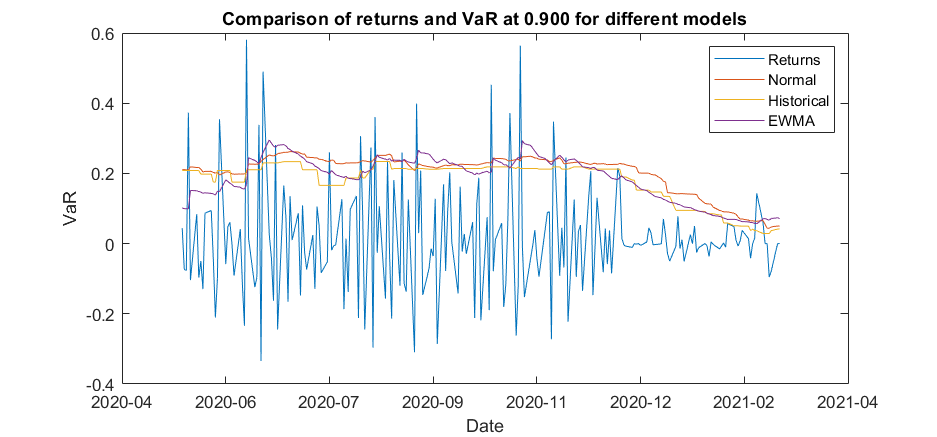



%------------------------------------------------------------------------------------------------------            
pVaR = 1 - VaRLevel;
Zscore   = norminv(pVaR);
Normal95 = zeros(length(TestWindow),1);

for t = TestWindow
    i = t - TestWindowStart + 1;
    EstimationWindow = t-EstimationWindowSize:t-1;
    Sigma = std(Returns(EstimationWindow));
    Normal95(i - EstimationWindowSize) = -Zscore(1)*Sigma;
end

Lambda = 0.94;
Sigma2     = zeros(length(Returns),1);
Sigma2(1)  = Returns(1)^2;

for i = 2 : (TestWindowStart-1)
    Sigma2(i) = (1-Lambda) * Returns(i-1)^2 + Lambda * Sigma2(i-1);
end
Zscore = norminv(pVaR);
EWMA95 = zeros(length(TestWindow),1);

for t = TestWindow
    k     = t - TestWindowStart + 1;
    Sigma2(t) = (1-Lambda) * Returns(t-1)^2 + Lambda * Sigma2(t-1);
    Sigma = sqrt(Sigma2(t));
    EWMA95(k - EstimationWindowSize) = -Zscore(1)*Sigma;
end
ReturnsTest = Returns(TestWindow);
DatesTest   = DateReturns(TestWindow);
date_ = datenum(DatesTest);
figure(5)
plot(date_,[ReturnsTest Normal95 -VaR_Hist EWMA95])
set(gcf,'position',[500,500,750,350])
datetick('x', 'yyyy-mm', 'keepticks');
ylabel( 'VaR')
xlabel('Date')
legend({'Returns','Normal','Historical','EWMA'},'Location','Northeast')
title(sprintf('Comparison of returns and VaR at %.3f for different models', VaRLevel))

Also, the functionality to change the start and end date and the signal lamp are included in the dashboard for comprehensiveness.

### Risk Matrix

The risk matrix is used to measure the sensitiveness of risk metrics with regard to the percentage change of underlying price and volatility. The users should be able to select different metrics, which they think, are relevant to the decision making. Different scales of changes are also included for the traders to monitor risks and get prepared for the worst senarios. Here, because the ListBox for multiple selection is not allowed, we leave the instructions in the demo video.

UnderlyingScale = "-10,-5,0";
VolScale = "0,5,10,-5";
data = readtable('matrix.csv','PreserveVariableNames',true);
und = UnderlyingScale;
und_array = split(und, ",");
len = length(und_array);
und_int = zeros(len,1);
for index = 1:len
    und_int(index) = str2num(und_array{index});
end
cond = ismember(data.("Underlying Pct"),und_int);
data = data(cond,:);
und = VolScale;
und_array = split(und, ",");
len = length(und_array);
und_int = zeros(len,1);
for index = 1:len
    und_int(index) = str2num(und_array{index});
end
cond = ismember(data.("Vol Pct"),und_int);
data = data(cond,:);

By adding the UI control, the matrix will be look like as follows:

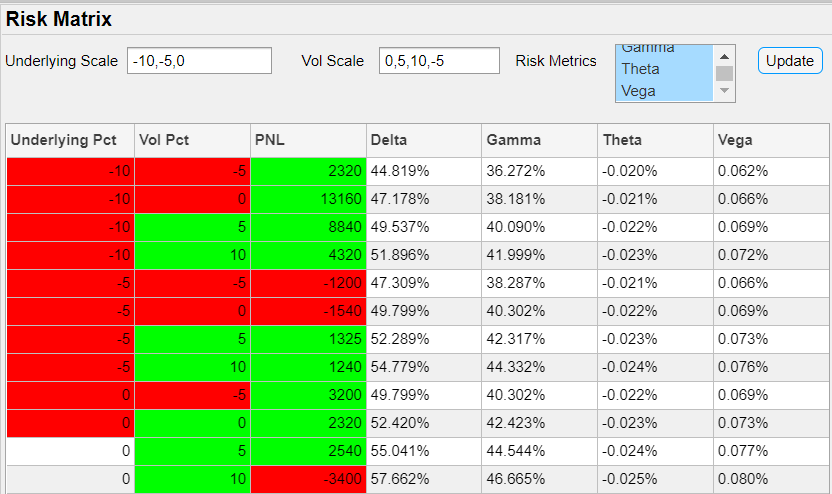

### Dynamic Delta Hedging

We simulate the underlying asset price with assuming geometric brownian motion using monte-carlo simulation. During the simulation period, we dynamically replicate the option portfolio using the underlying asset and risk free aset. As we can see from the plot, our replicating portfolio have the relative same performance as  the option movement.

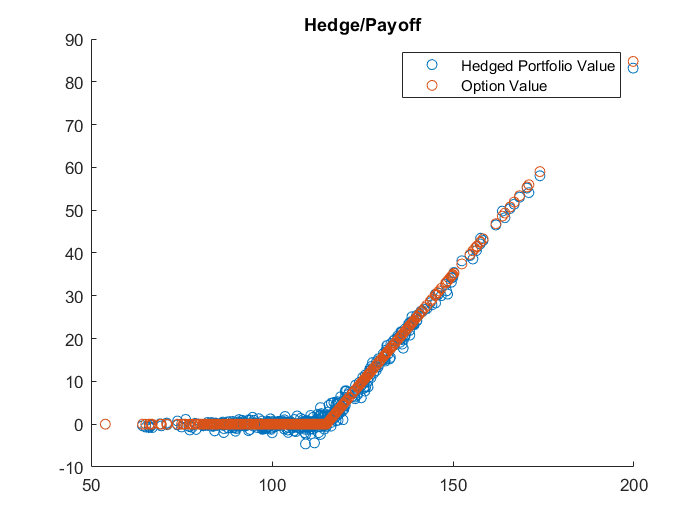

S_0 = 100.0;
T = 1.0;
K = S_0 * 1.15;
r = 0.05;
mu = 0.1;
sigma = 0.2;
Nhedgepoints = 52;
Npaths = 500;
dt = T/Nhedgepoints;
S_t = zeros(Npaths,1);
Payoff = zeros(Npaths,1);
Hedge = zeros(Npaths,1);
Error = zeros(Npaths,1);
v = zeros(Nhedgepoints + 1, 1);
S = S_0;

for j = 1:Npaths
    
    %Delta Hedge
    S = S_0;
    V = BSMOption("Call",S,T,K,r,sigma,"Price");
    a = BSMOption("Call",S,T,K,r,sigma,"Delta");
    b = V-a*S;
    for i = 0:Nhedgepoints
        eps = normrnd(0,1);
        S = S*exp((mu-0.5*sigma^2)*dt+sigma*sqrt(dt)*eps);
        
        V = a*S+b*exp(r*dt);
        T_i = T-i*dt;
        a = BSMOption("Call",S,T_i,K,r,sigma,"Delta");
        b = V - a*S;
    end
    S_t(j) = S;
    Hedge(j) = V;
    Payoff(j) = BSMOption("Call",S,0,K,r,sigma,"Price");
end
figure(1);
scatter(S_t, Hedge);
hold on;
scatter(S_t, Payoff);
title("Hedge/Payoff");
legend('Hedged Portfolio Value','Option Value')